# stim dummy

## Pain > (Vicarious & Cognitive)

#### Pain > VC :: load dataset

clear all;
close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0013.nii'));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0013.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 6.048302 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9220940  Bit rate: 23.14 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Pain > VC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              16:35:22 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Pain > VC :: Plot diagnostics, before l2norm

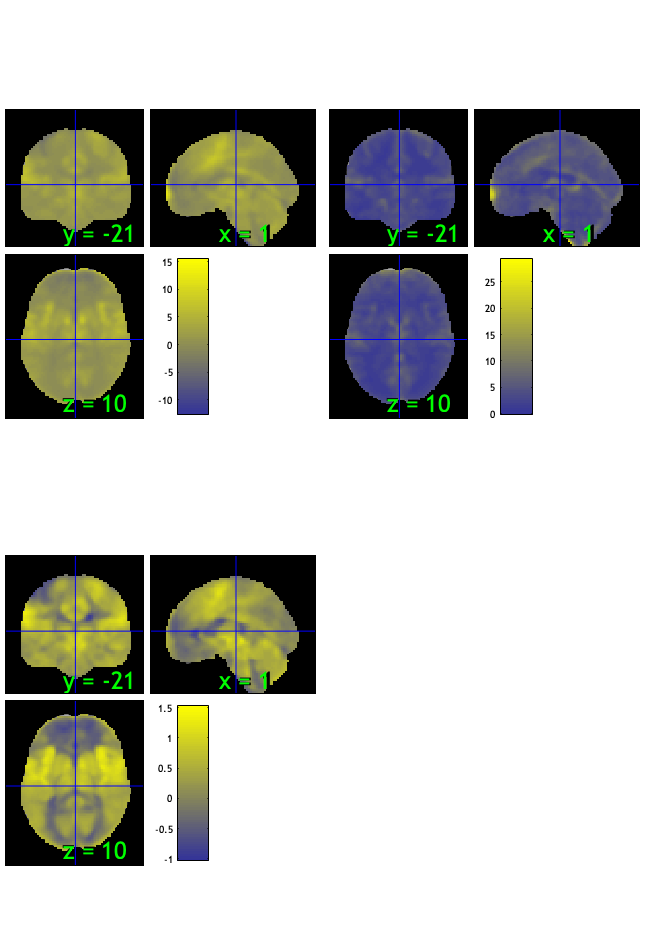

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 19.59%
Expected 4.85 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 26 27 73 
Uncorrected: 5 images		Cases 6 26 27 35 73 

Retained 6 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.45%
Expected 4.85 outside 95% ellipsoid, found   3

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 3 images		Cases 14 61 68 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               <s

SPM12: spm_check_registration (v7759)              16:35:57 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

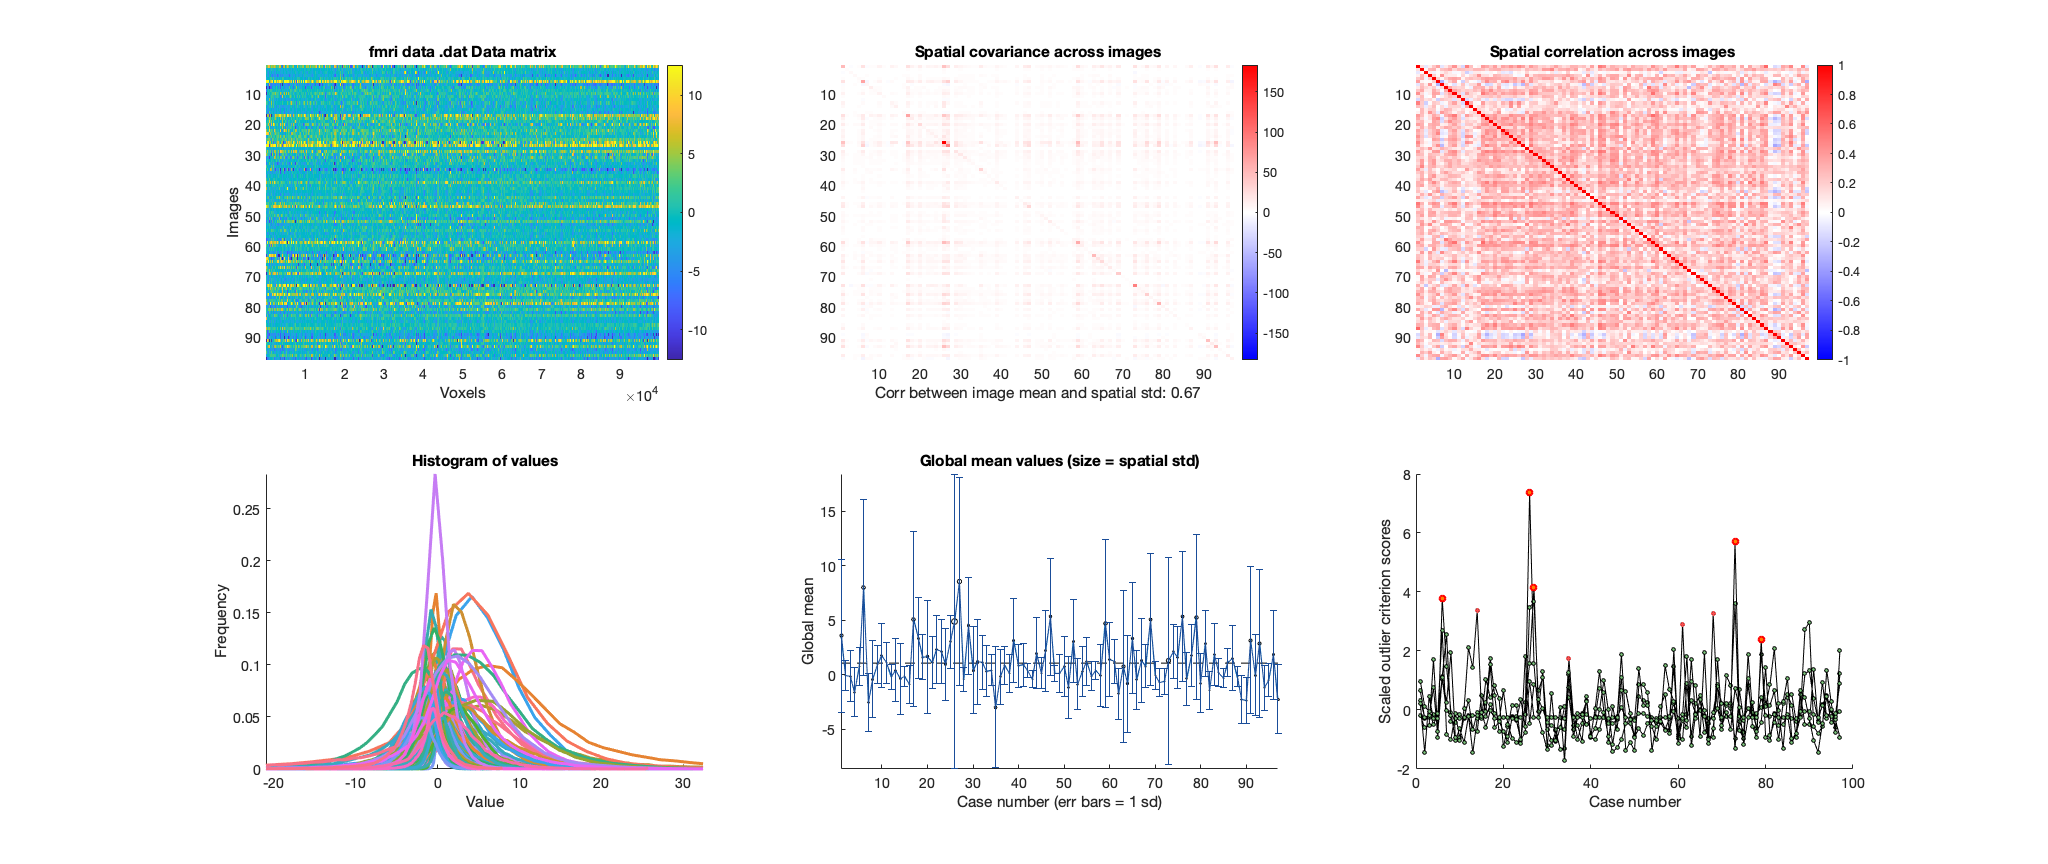

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain > VC :: run robfit

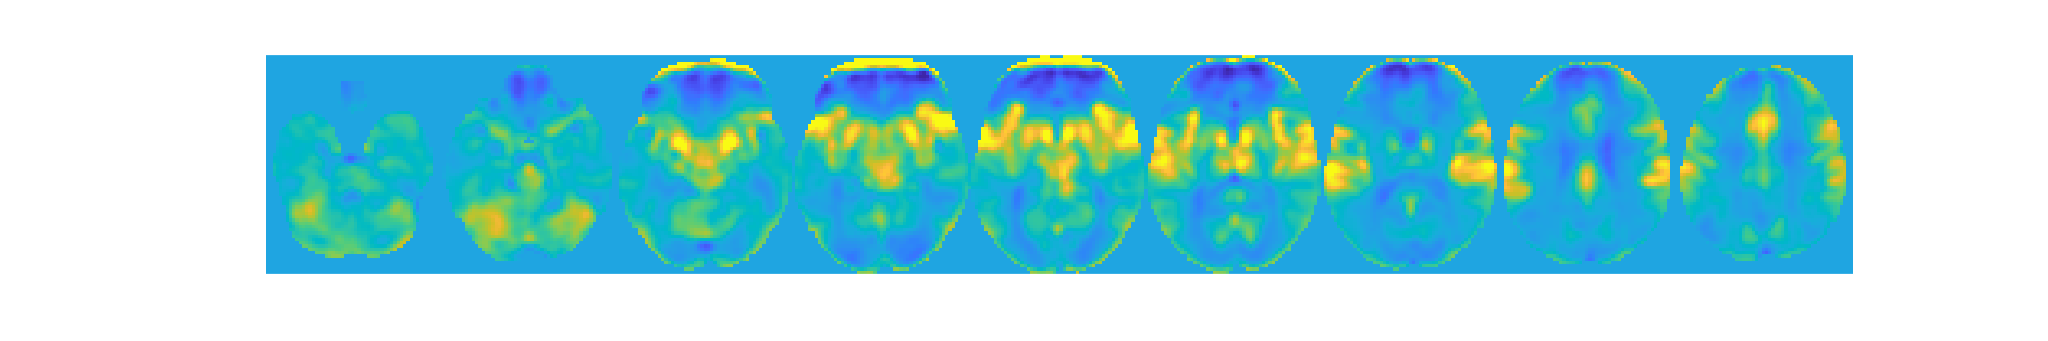

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain > VC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 97


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 5 participants, size is now 92


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"



disp(n);

    {'sub-0018'}    {'sub-0043'}    {'sub-0044'}    {'sub-0102'}    {'sub-0111'}



#### Pain > VC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain > VC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


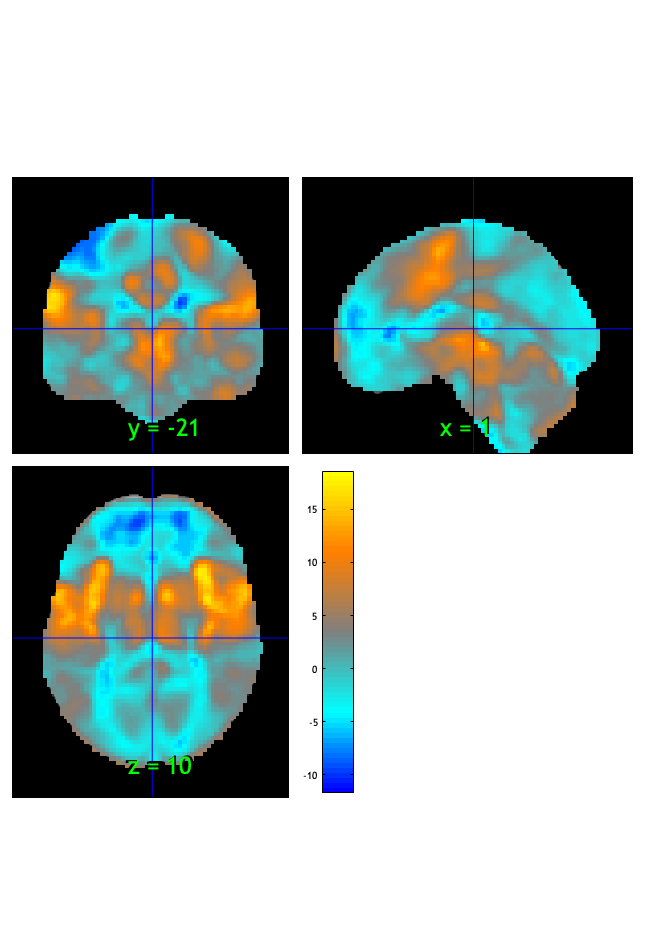

SPM12: spm_check_registration (v7759)              16:36:02 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.026944

Image   1
 39 contig. clusters, sizes   1 to 53419
Positive effect: 37808 voxels, min p-value: 0.00000000
Negative effect: 16004 voxels, min p-value: 0.00000000


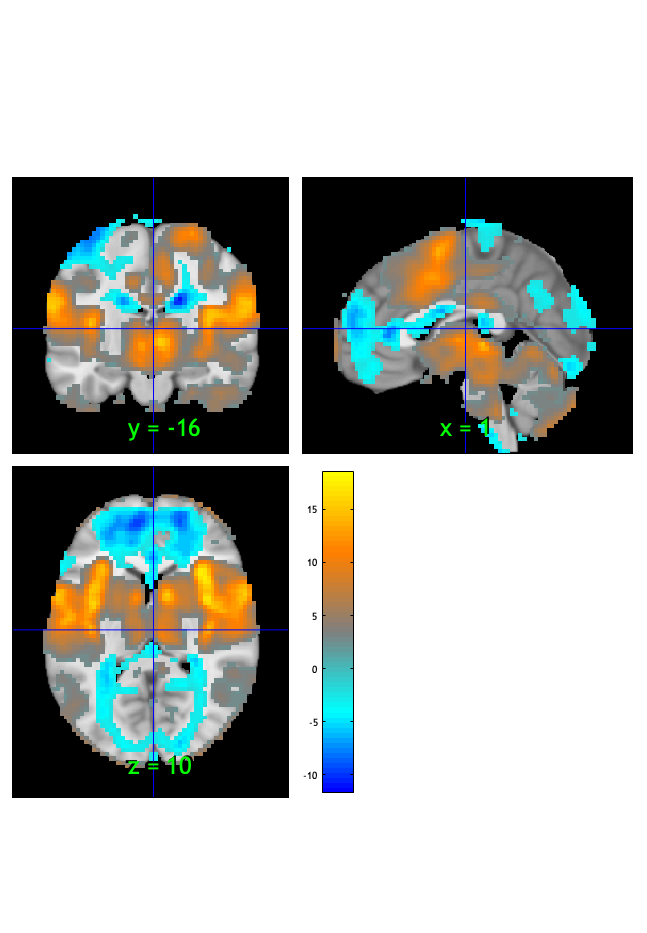

SPM12: spm_check_registration (v7759)              16:36:04 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

drawnow, snapnow;

fdr_t = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000322

Image   1
 54 contig. clusters, sizes   1 to 30328
Positive effect: 24792 voxels, min p-value: 0.00000000
Negative effect: 7349 voxels, min p-value: 0.00000000


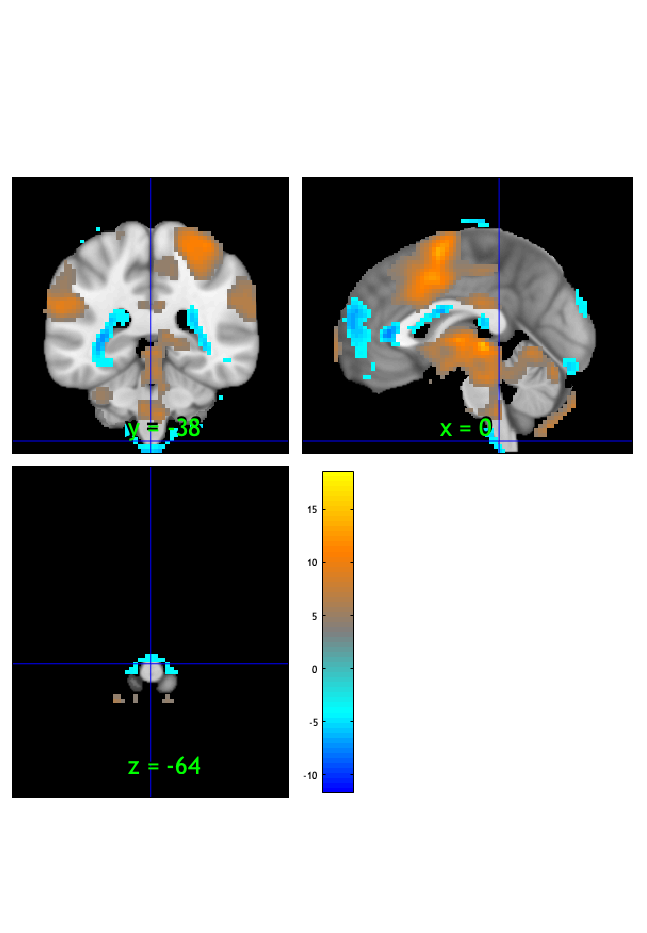

SPM12: spm_check_registration (v7759)              16:36:05 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


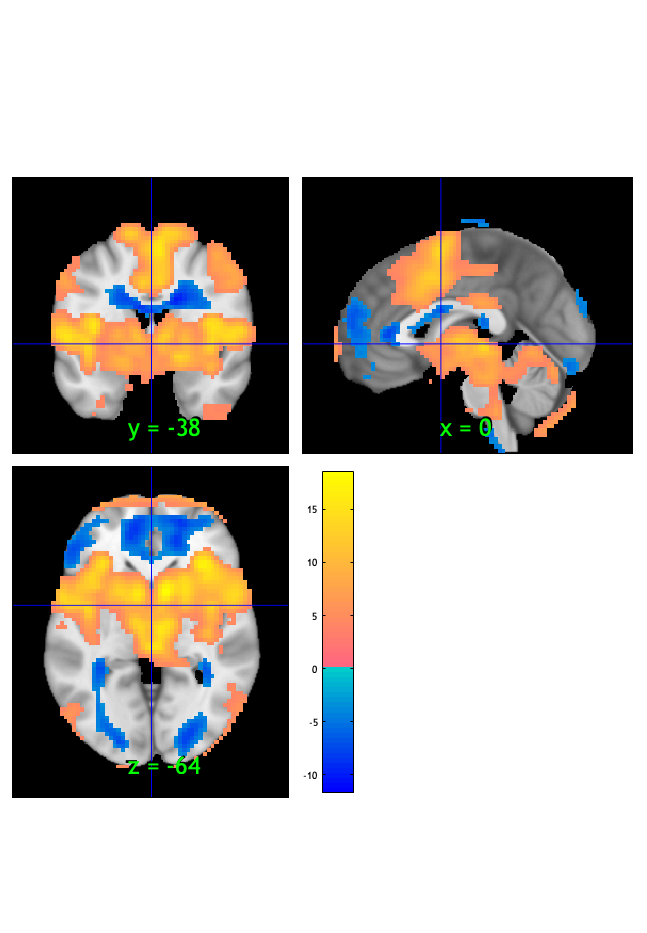

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 789 voxels displayed, 31352 not displayed on these slices


sagittal montage: 964 voxels displayed, 31177 not displayed on these slices


sagittal montage: 810 voxels displayed, 31331 not displayed on these slices


axial montage: 5993 voxels displayed, 26148 not displayed on these slices


axial montage: 6354 voxels displayed, 25787 not displayed on these slices


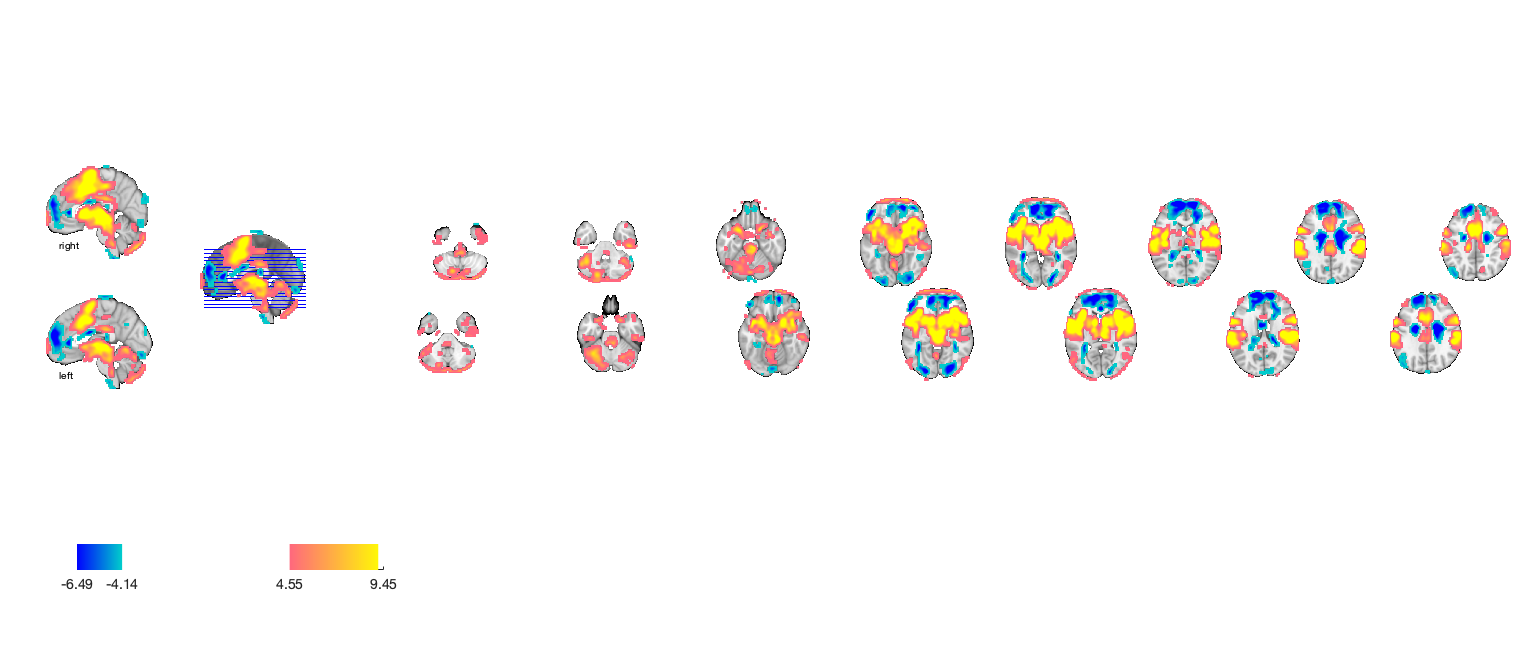

drawnow, snapnow;

#### Pain > VC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low       testr_high       words_high    
    _________    _______________    __________    _________________

    -0.28767     {'judgment'   }     0.38991      {'pain'         }
    -0.26676     {'judgments'  }     0.37686      {'painful'      }
    -0.25368     {'recognition'}     0.36702      {'somatosensory'}
    -0.25273     {'memory'     }      0.3376      {'heat'         }
     -0.2313     {'mental'     }      0.3369      {'noxious'      }
    -0.22352     {'episodic'   }     0.33532      {'sensory'      }
    -0.21747     {'person'     }     0.32859      {'stimulation'  }
    -0.21463     {'intention'  }     0.31132      {'sensation'    }
    -0.21418     {'object'     }     0.30655      {'motor'        }
    -0.20837

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain > VC :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.1141	16.4733	0.0000	1.0000	
Cog Wholebrain	-0.0627	-17.0935	0.0000	1.0000	
Emo Wholebrain	-0.0520	-9.1946	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.11412     0.0068764     16.596    2.2204e-15       1.685
    {'Cog Wholebrain' }    -0.062666     0.0036541     -17.15    2.2204e-15     -1.7413
    {'Emo Wholebrain' }     -0.05198      0.005645    -9.2083    7.4385e-15    -0.93496



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [9.0001 10.0001 11.0001]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}      0.10567     0.0065342     16.172    2.2204e-15       1.642
    {'Cog Wholebrain' }     -0.05661     0.0034513    -16.402    2.2204e-15     -1.6654
    {'Emo Wholebrain' }    -0.049163     0.0054131    -9.0823    1.3878e-14    -0.92217



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [12.0001 13.0001 14.0001]


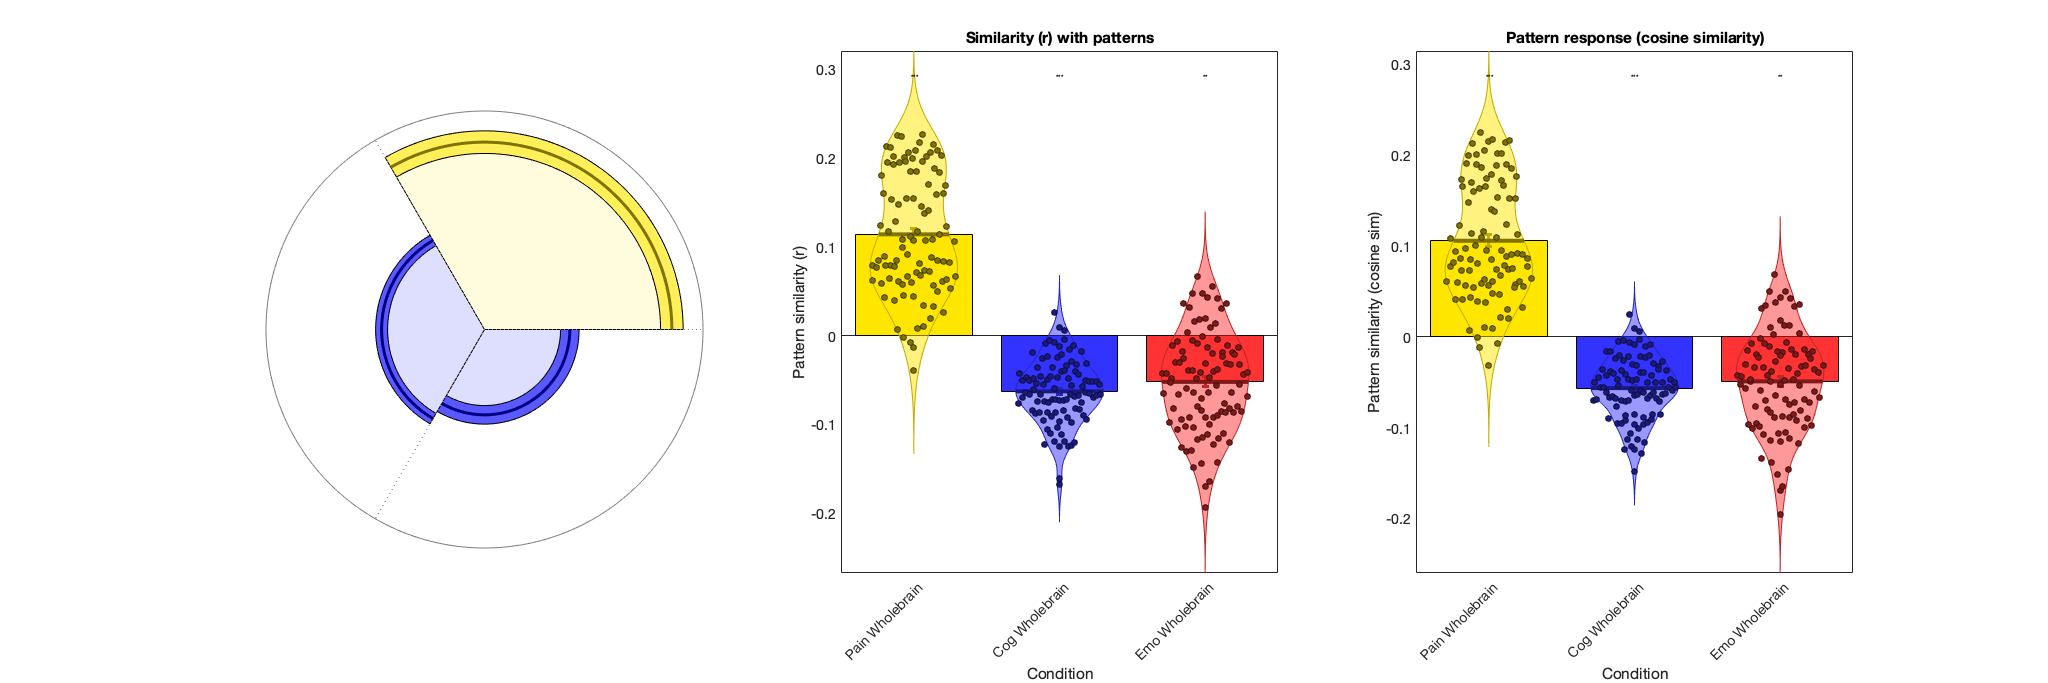

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious > (Pain & Cognitive)

clear all;
close all;

#### Vicarious > PC :: load dataset

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0014.nii'));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0014.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 6.088255 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9227756  Bit rate: 23.14 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Vicarious > PC :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              16:37:54 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious > PC :: Plot diagnostics, before l2norm

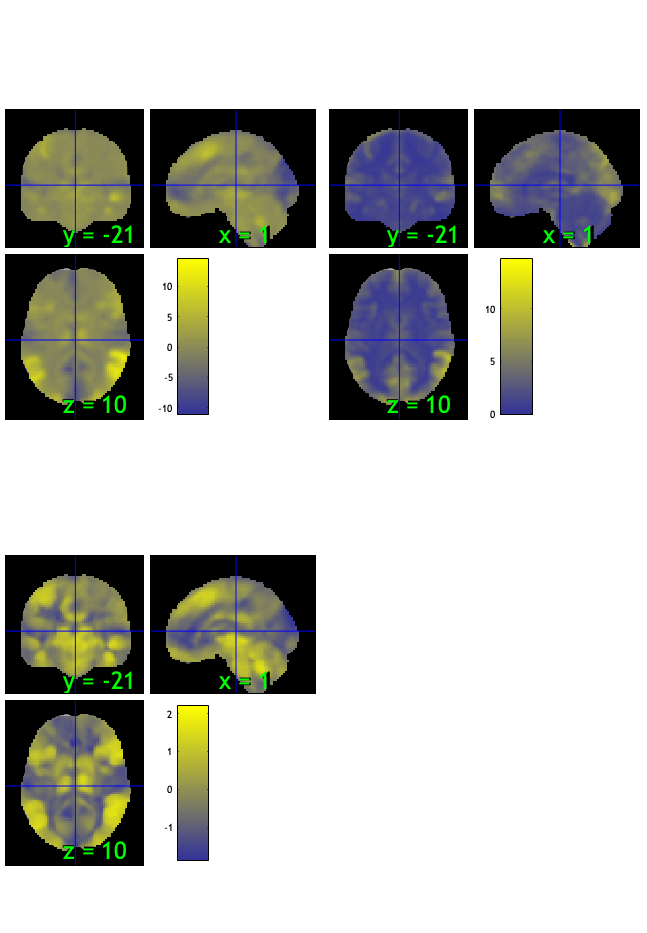

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 36.08%
Expected 4.85 outside 95% ellipsoid, found  12

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 97 
Uncorrected: 12 images		Cases 22 30 39 52 60 61 64 75 77 89 93 97 

Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 50.52%
Expected 4.85 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 4 images		Cases 5 54 63 68 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
              

SPM12: spm_check_registration (v7759)              16:38:27 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

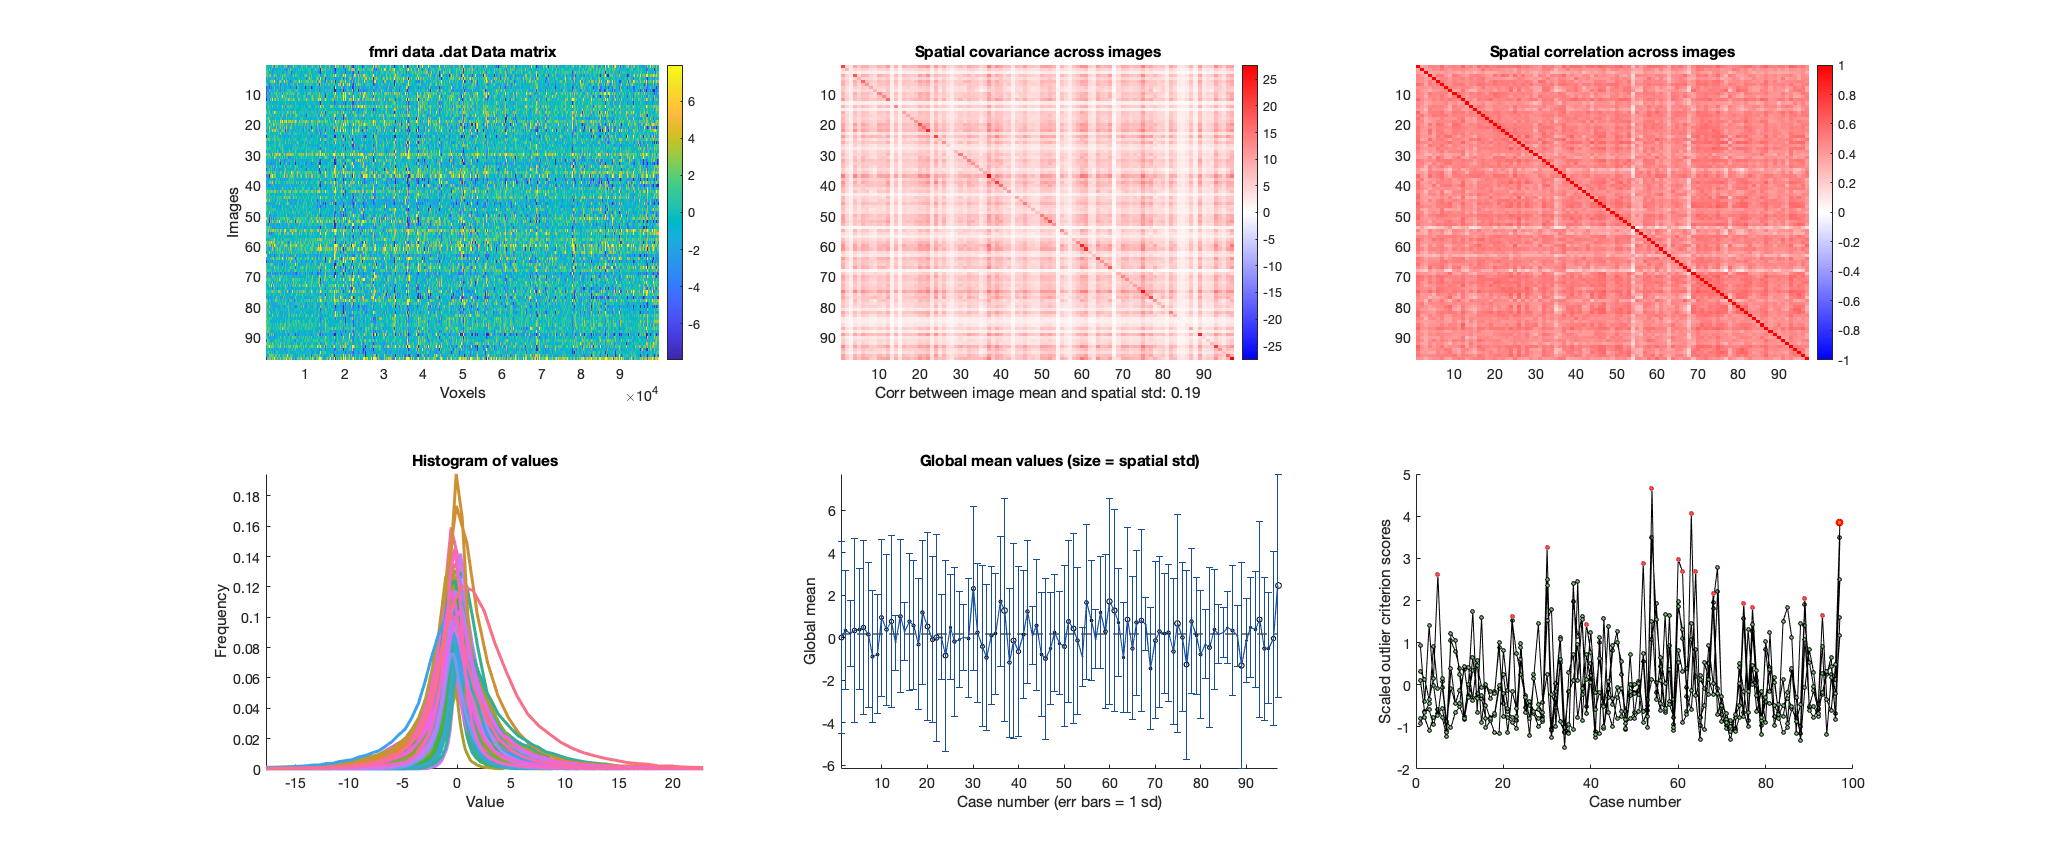

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious > PC :: run robfit

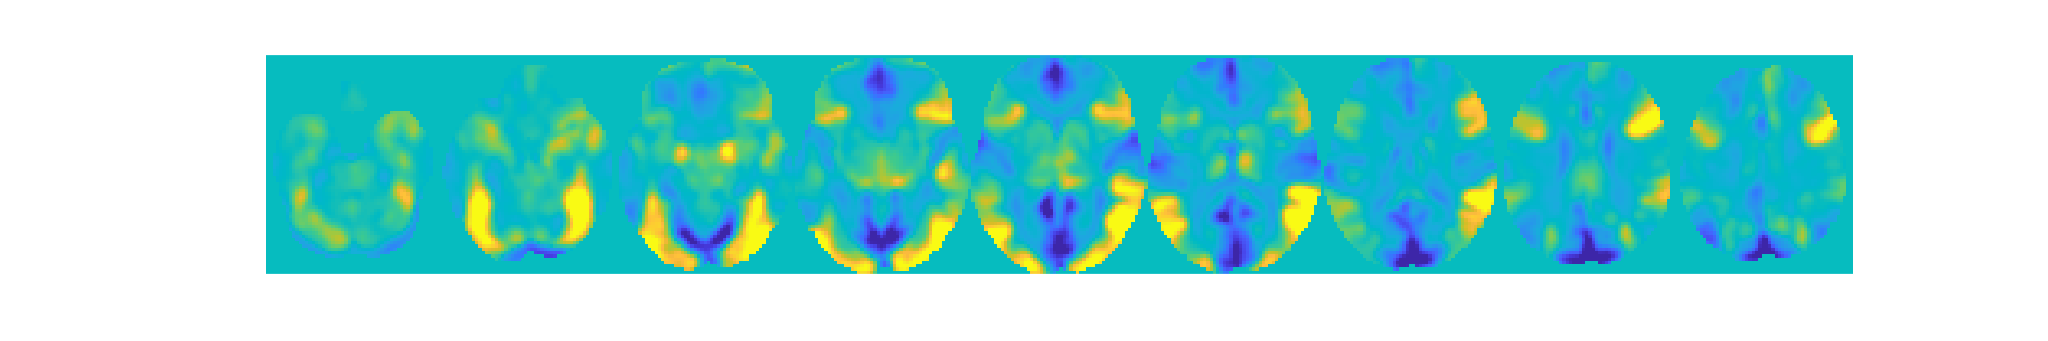

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious > PC :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 97


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 1 participants, size is now 96


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

participants that are outliers:... sub-0133


disp(n);

sub-0133


#### Vicarious > PC :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious > PC :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


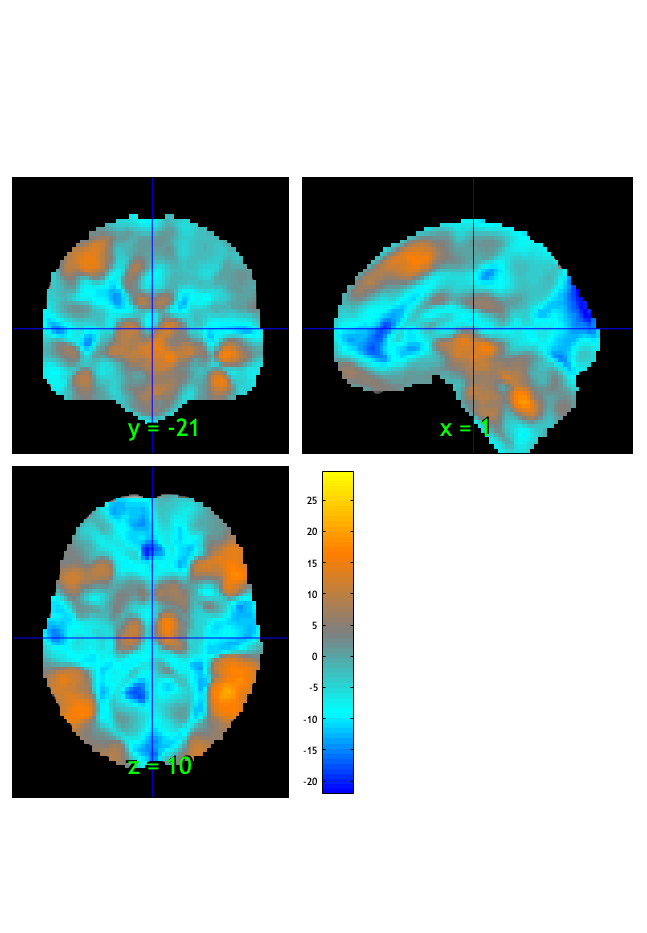

SPM12: spm_check_registration (v7759)              16:38:31 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.038830

Image   1
 15 contig. clusters, sizes   1 to 77459
Positive effect: 35384 voxels, min p-value: 0.00000000
Negative effect: 42164 voxels, min p-value: 0.00000000


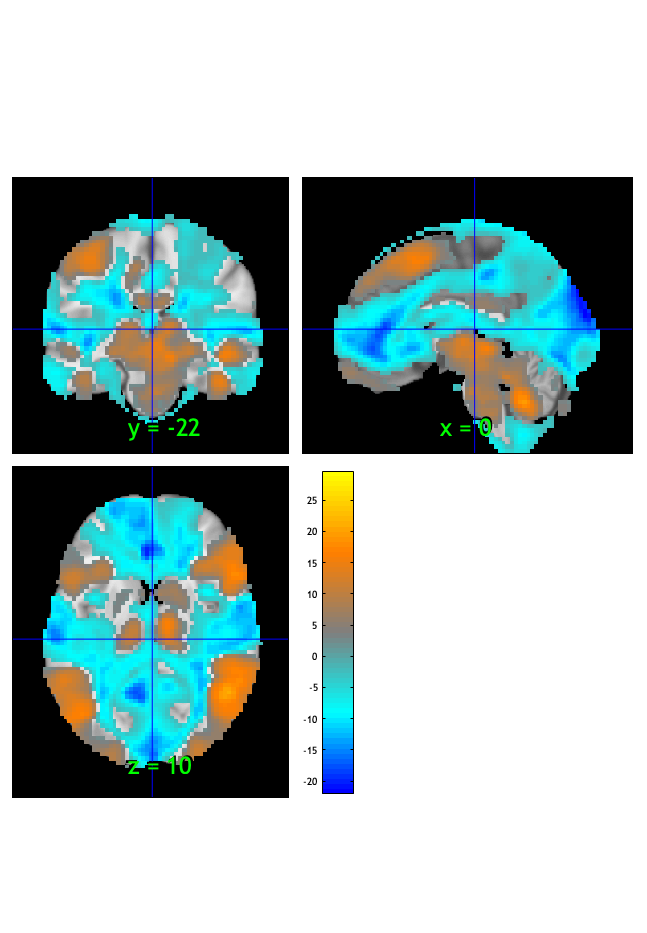

SPM12: spm_check_registration (v7759)              16:38:34 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t);

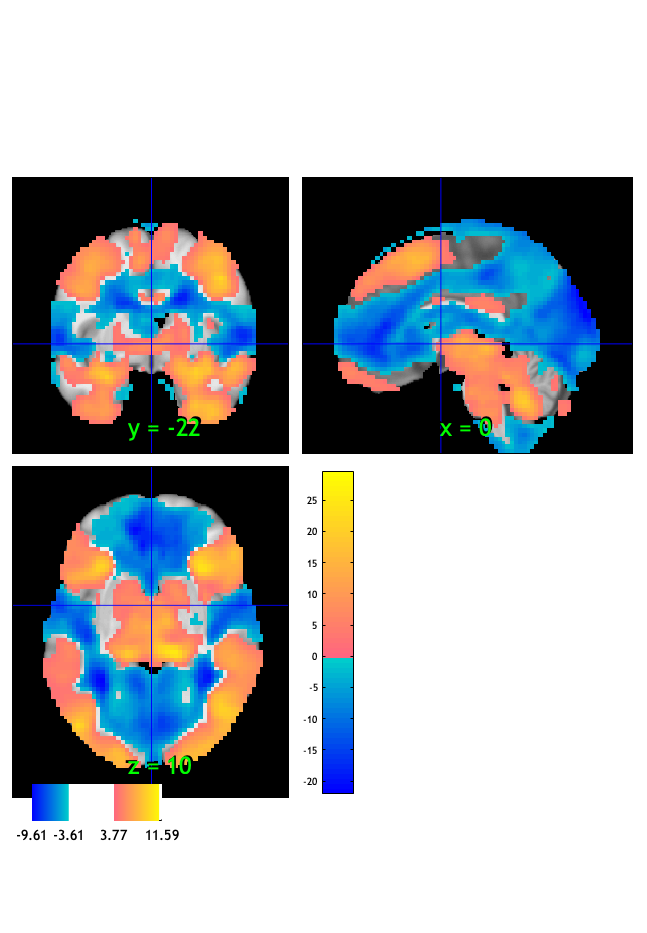

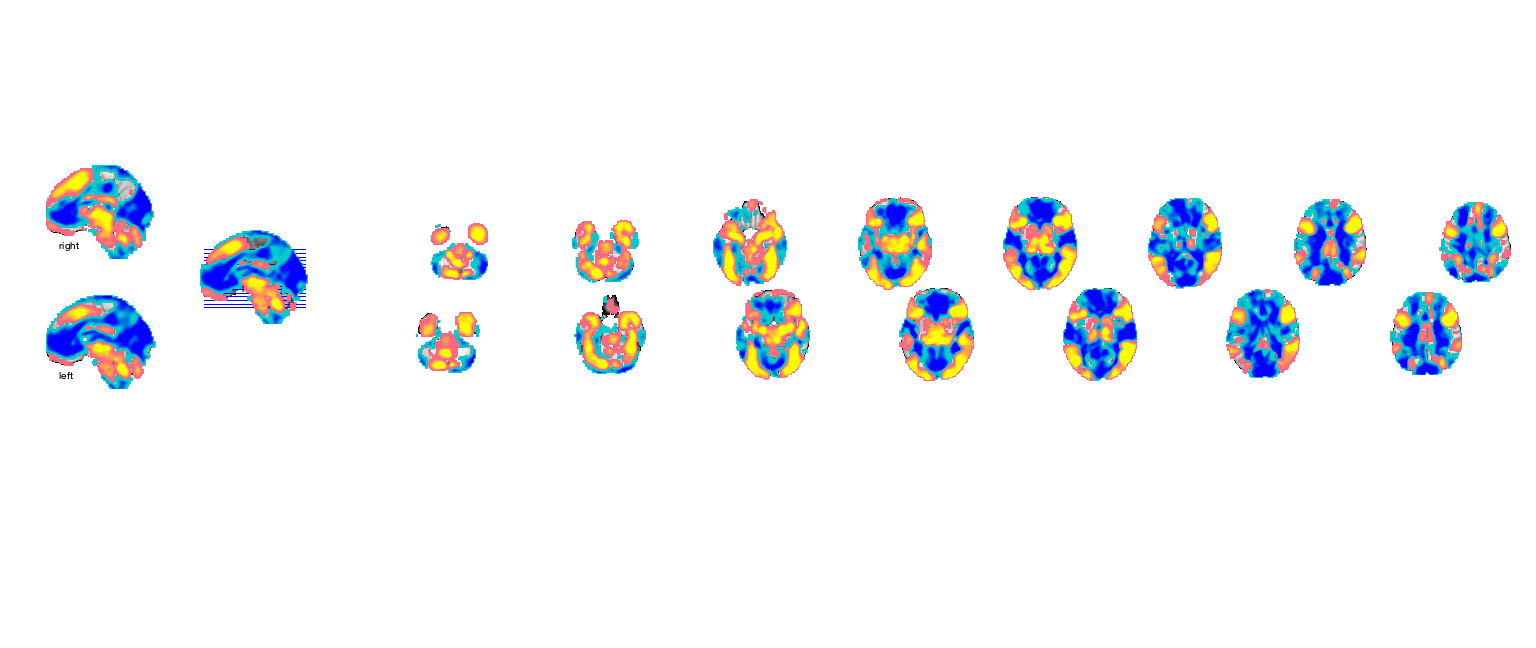

Setting up fmridisplay objects


sagittal montage: 2030 voxels displayed, 75518 not displayed on these slices


sagittal montage: 1914 voxels displayed, 75634 not displayed on these slices


sagittal montage: 1978 voxels displayed, 75570 not displayed on these slices


axial montage: 14830 voxels displayed, 62718 not displayed on these slices


axial montage: 16008 voxels displayed, 61540 not displayed on these slices


drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

drawnow, snapnow;

#### Vicarious > PC :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high      words_high  
    _________    ________________    __________    ______________

    -0.26128     {'age'         }     0.27158      {'visual'    }
    -0.24946     {'time'        }     0.26781      {'object'    }
    -0.21976     {'restingstate'}     0.26299      {'perception'}
     -0.2195     {'default'     }     0.26121      {'identity'  }
    -0.21668     {'disorder'    }     0.25281      {'objects'   }
    -0.20485     {'depression'  }     0.25181      {'face'      }
    -0.20466     {'trait'       }     0.24515      {'gesture'   }
    -0.20325     {'personal'    }     0.24203      {'faces'     }
    -0.20274     {'outcomes'    }     0.22934      {'actions'   }
    -0.20005     {'positive'    } 

Vicarious > PC **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.1427	-32.0068	0.0000	1.0000	
Cog Wholebrain	-0.0274	-10.7682	0.0000	1.0000	
Emo Wholebrain	0.1595	35.8852	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14272     0.0043995     -32.44    2.2204e-15    -3.2937 
    {'Cog Wholebrain' }    -0.027358     0.0025398    -10.772    2.2204e-15    -1.0937 
    {'Emo Wholebrain' }      0.15951     0.0043703     36.498    2.2204e-15     3.7058 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [9.0002 10.0002 11.0002]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.14218     0.0043648    -32.574    2.2204e-15    -3.3074 
    {'Cog Wholebrain' }    -0.026193     0.0024266    -10.794    2.2204e-15     -1.096 
    {'Emo Wholebrain' }      0.16033     0.0043689     36.697    2.2204e-15      3.726 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [12.0002 13.0002 14.0002]


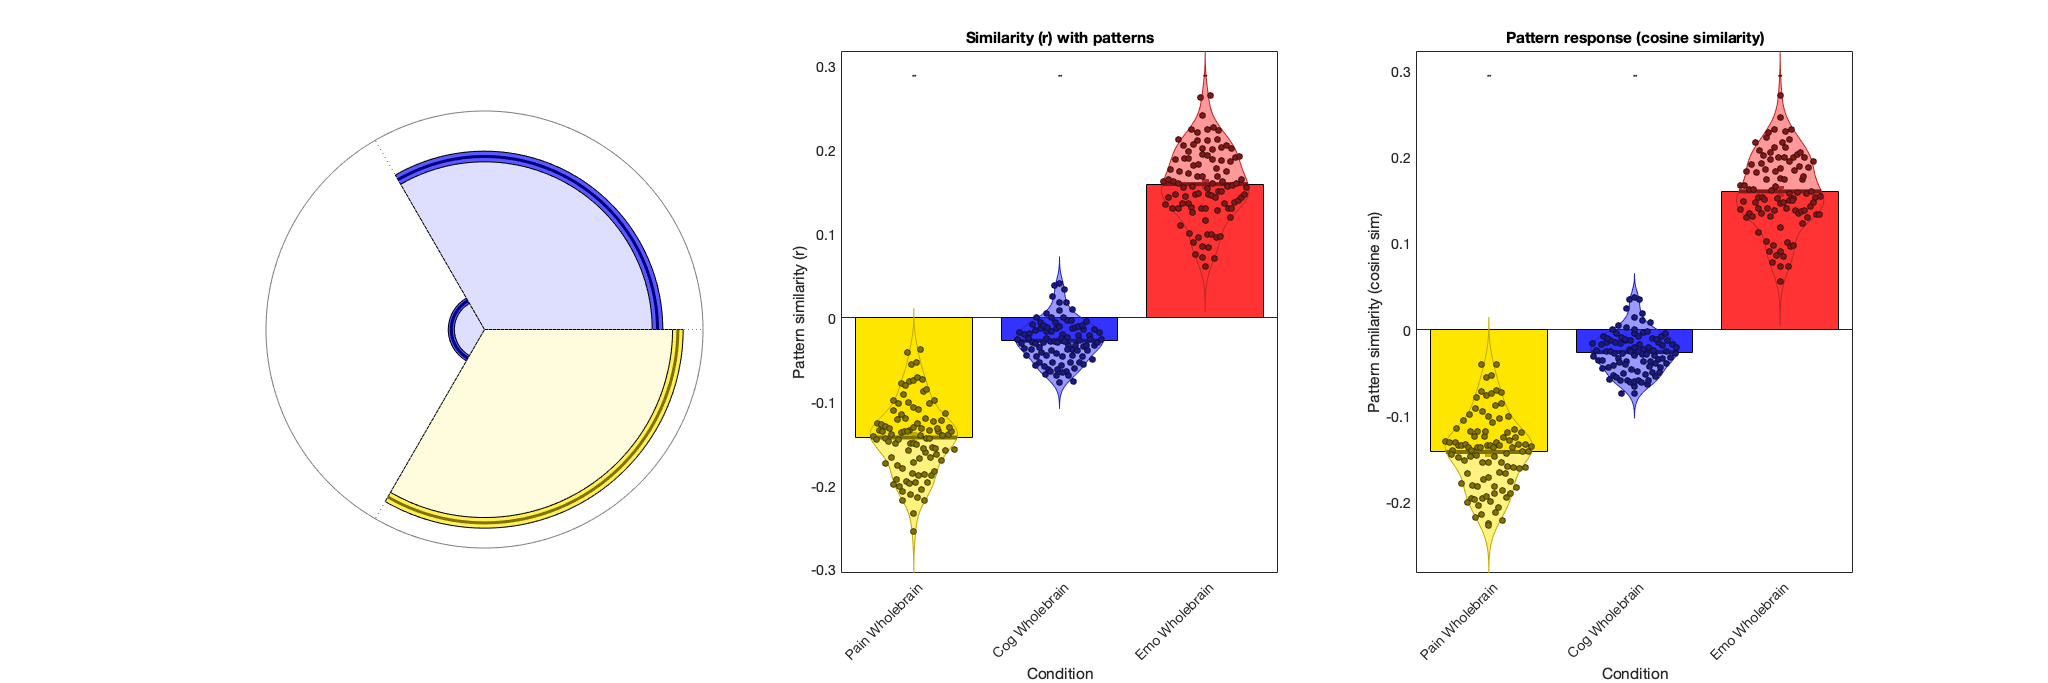

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive > (Pain & Vicarious)

#### Cognitive > PV :: load dataset

clear all; close all;
mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel';
con_list = dir(fullfile(mount_dir, '*/con_0015.nii'));
spm('Defaults','fMRI');
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.


sampleto = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_CESO/1stLevel/sub-0013/con_0015.nii'

loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 38736756 bytes
Loading image number:    97
Elapsed time is 5.865147 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 9227553  Bit rate: 23.14 bits


contrast_name = {'cue_P', 'cue_V', 'cue_C', 'cue_G',...
    'stim_P', 'stim_V', 'stim_C', 'stim_G',...
    'motor', ...
    'simple_cue_P', 'simple_cue_V', 'simple_cue_C', ...
    'simple_stim_P', 'simple_stim_V', 'simple_stim_C'};

#### Cognitive > PV :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              16:39:56 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


Grouping contiguous voxels:   1 regions


#### Cognitive > PV :: Plot diagnostics, before l2norm

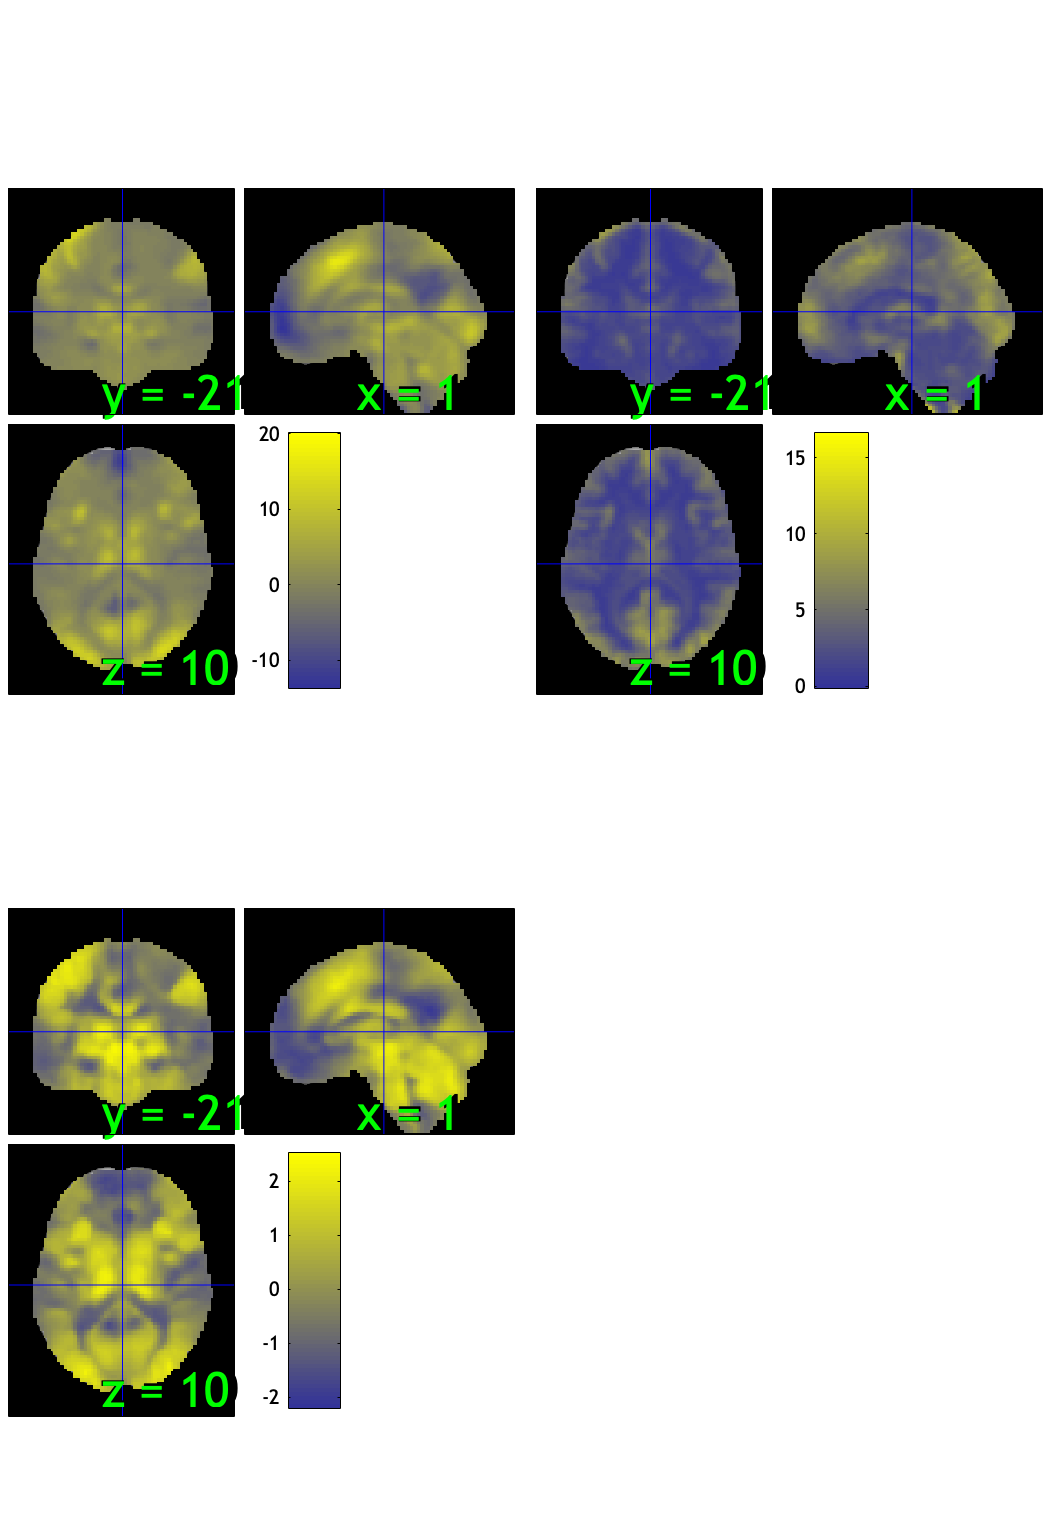

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.45%
Expected 4.85 outside 95% ellipsoid, found   7

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 7 images		Cases 20 37 59 61 82 89 97 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.45%
Expected 4.85 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 3 
Uncorrected: 4 images		Cases 3 5 30 54 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               <

SPM12: spm_check_registration (v7759)              16:40:39 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

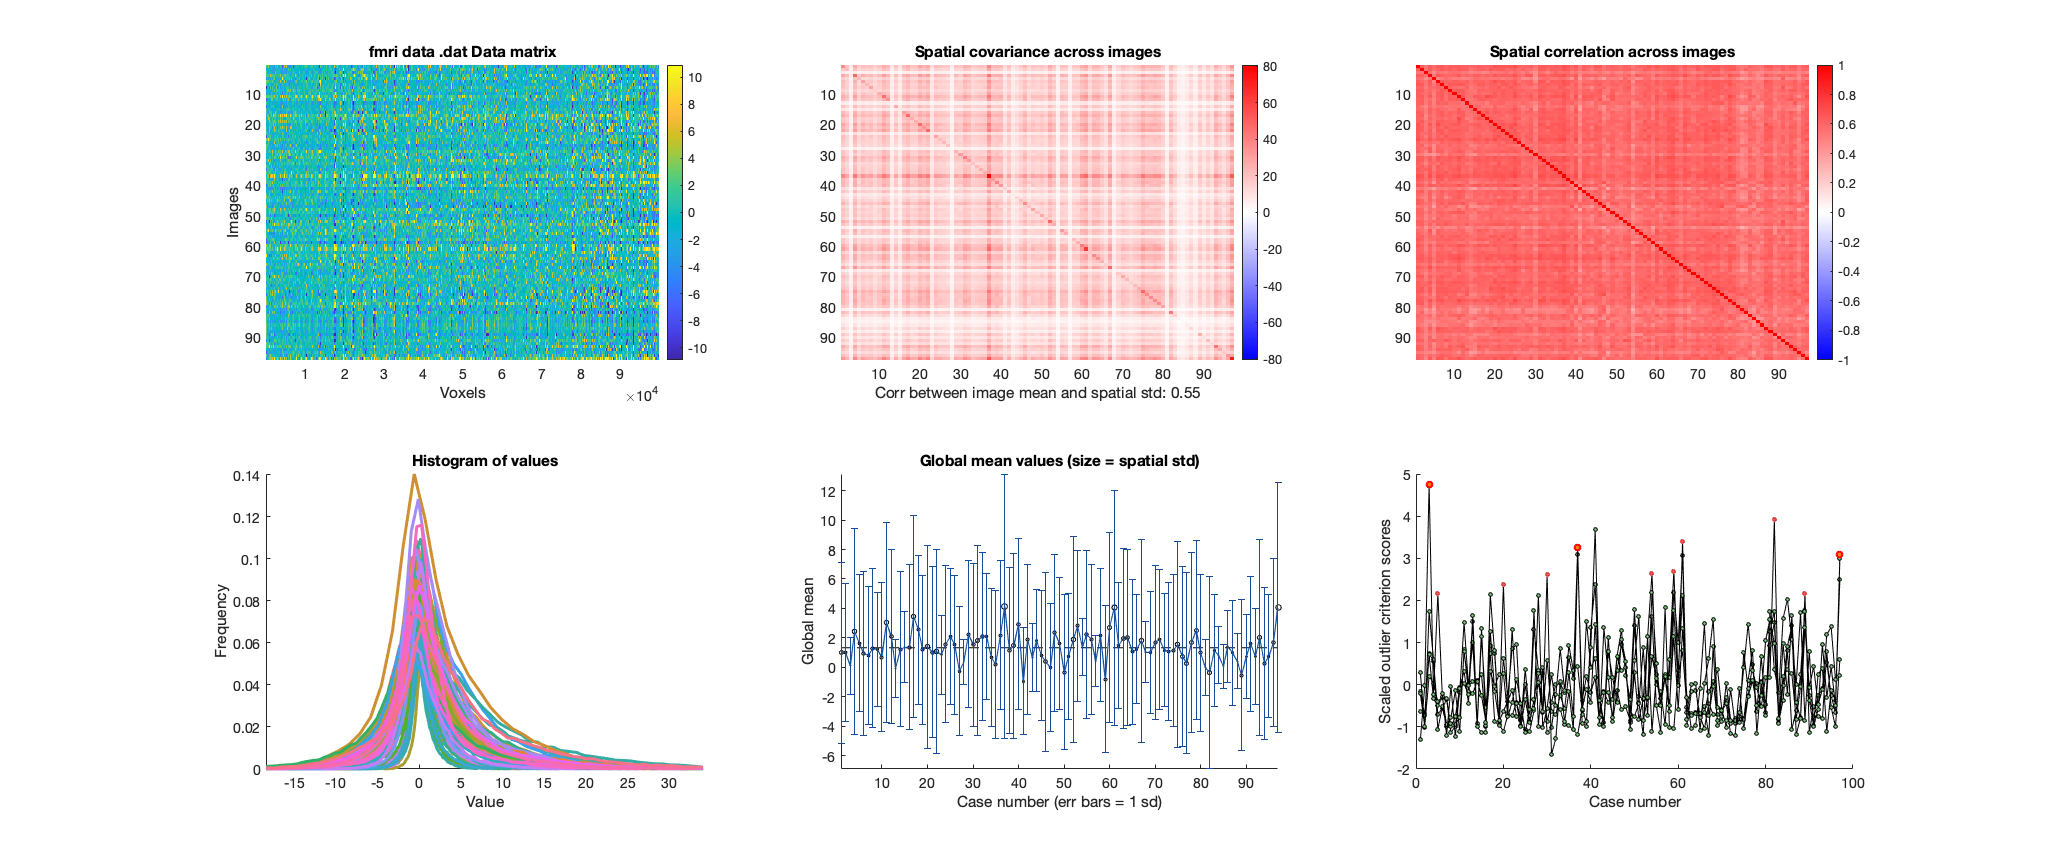

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive > PV :: run robfit

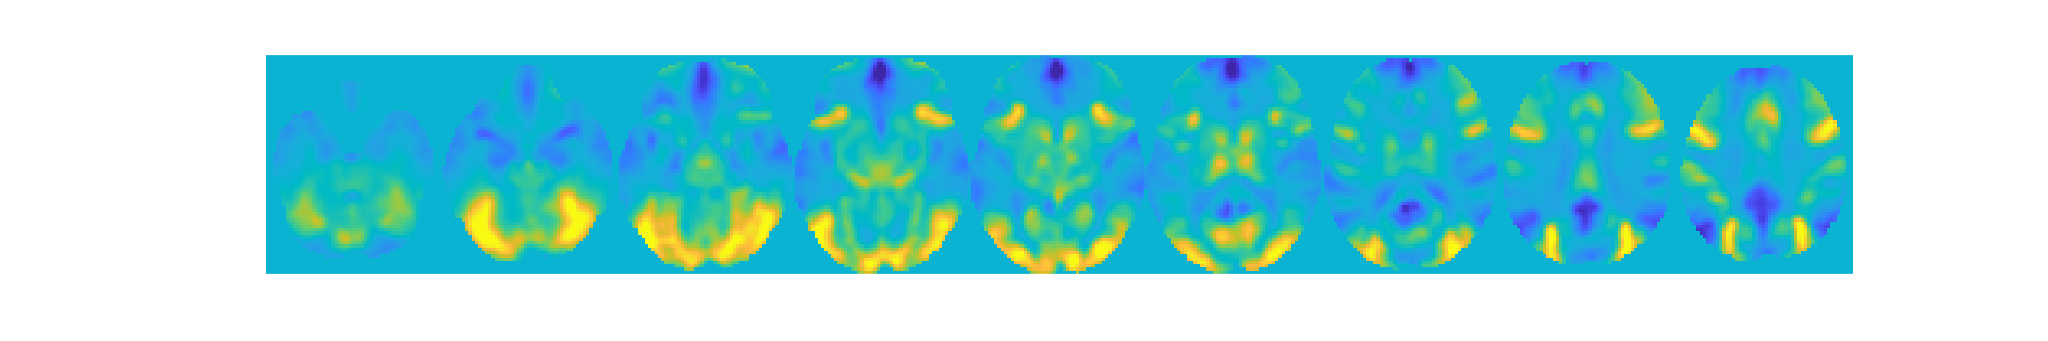

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive > PV :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 97


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 94


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0015"    "participants that are outliers:... sub-0059"    "participants that are outliers:... sub-0133"



disp(n);

    {'sub-0015'}    {'sub-0059'}    {'sub-0133'}



#### Cognitive > PV:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive > PV :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


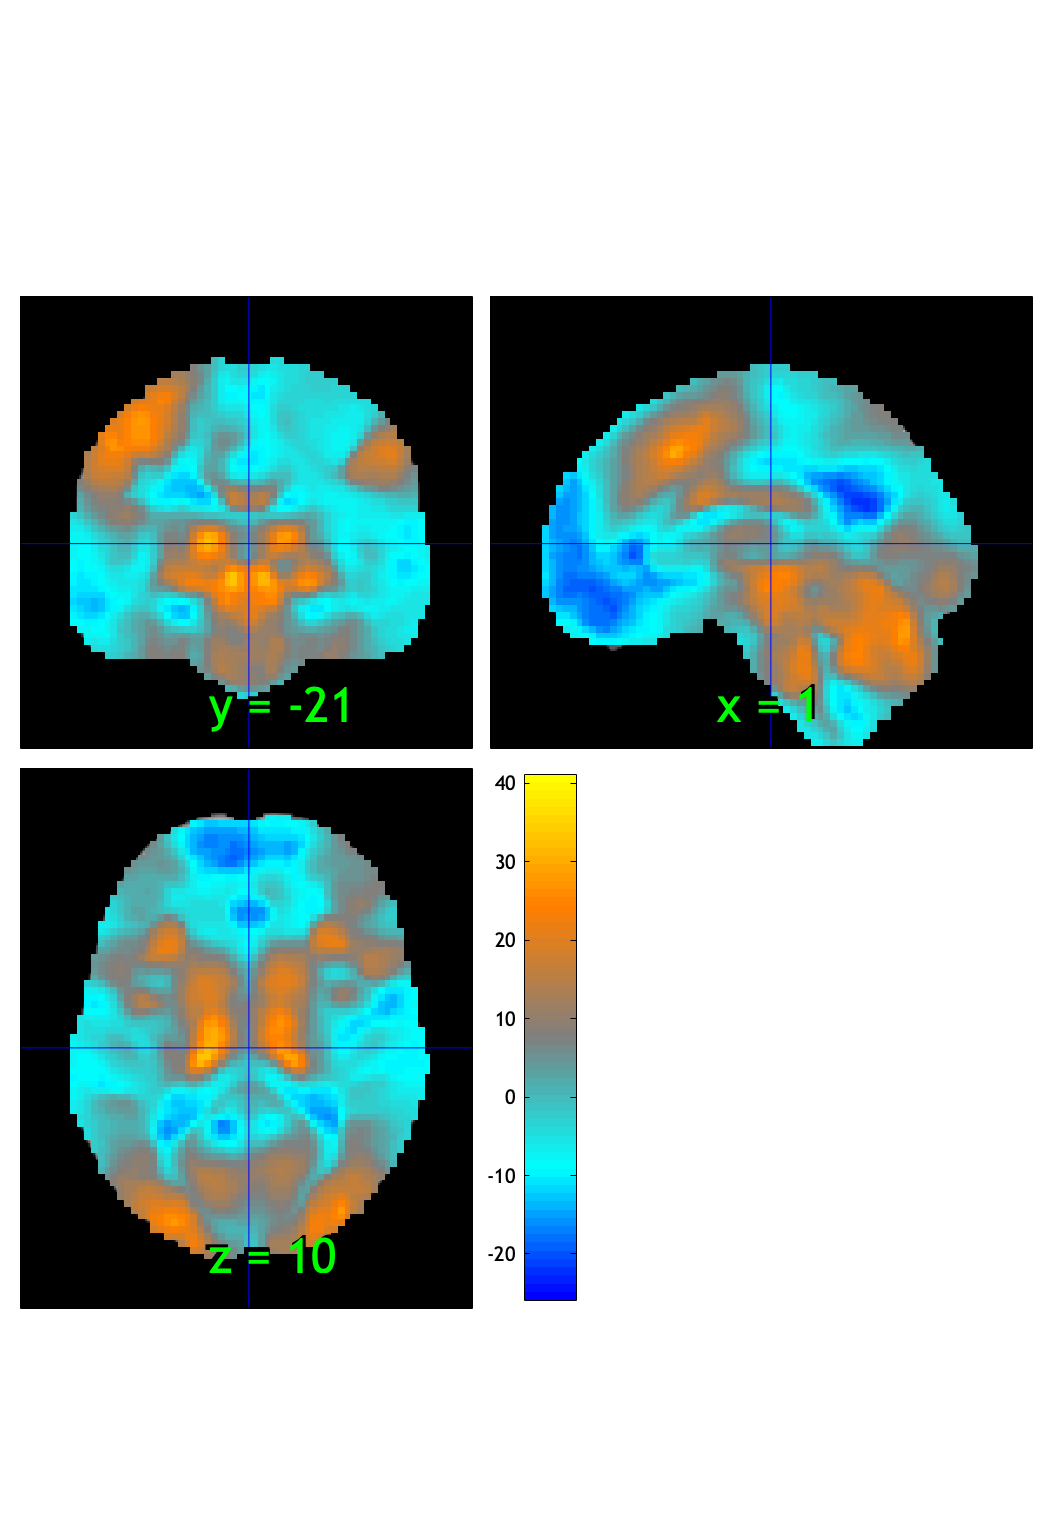

SPM12: spm_check_registration (v7759)              16:40:48 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.043035

Image   1
  1 contig. clusters, sizes 85982 to 85982
Positive effect: 50254 voxels, min p-value: 0.00000000
Negative effect: 35728 voxels, min p-value: 0.00000000


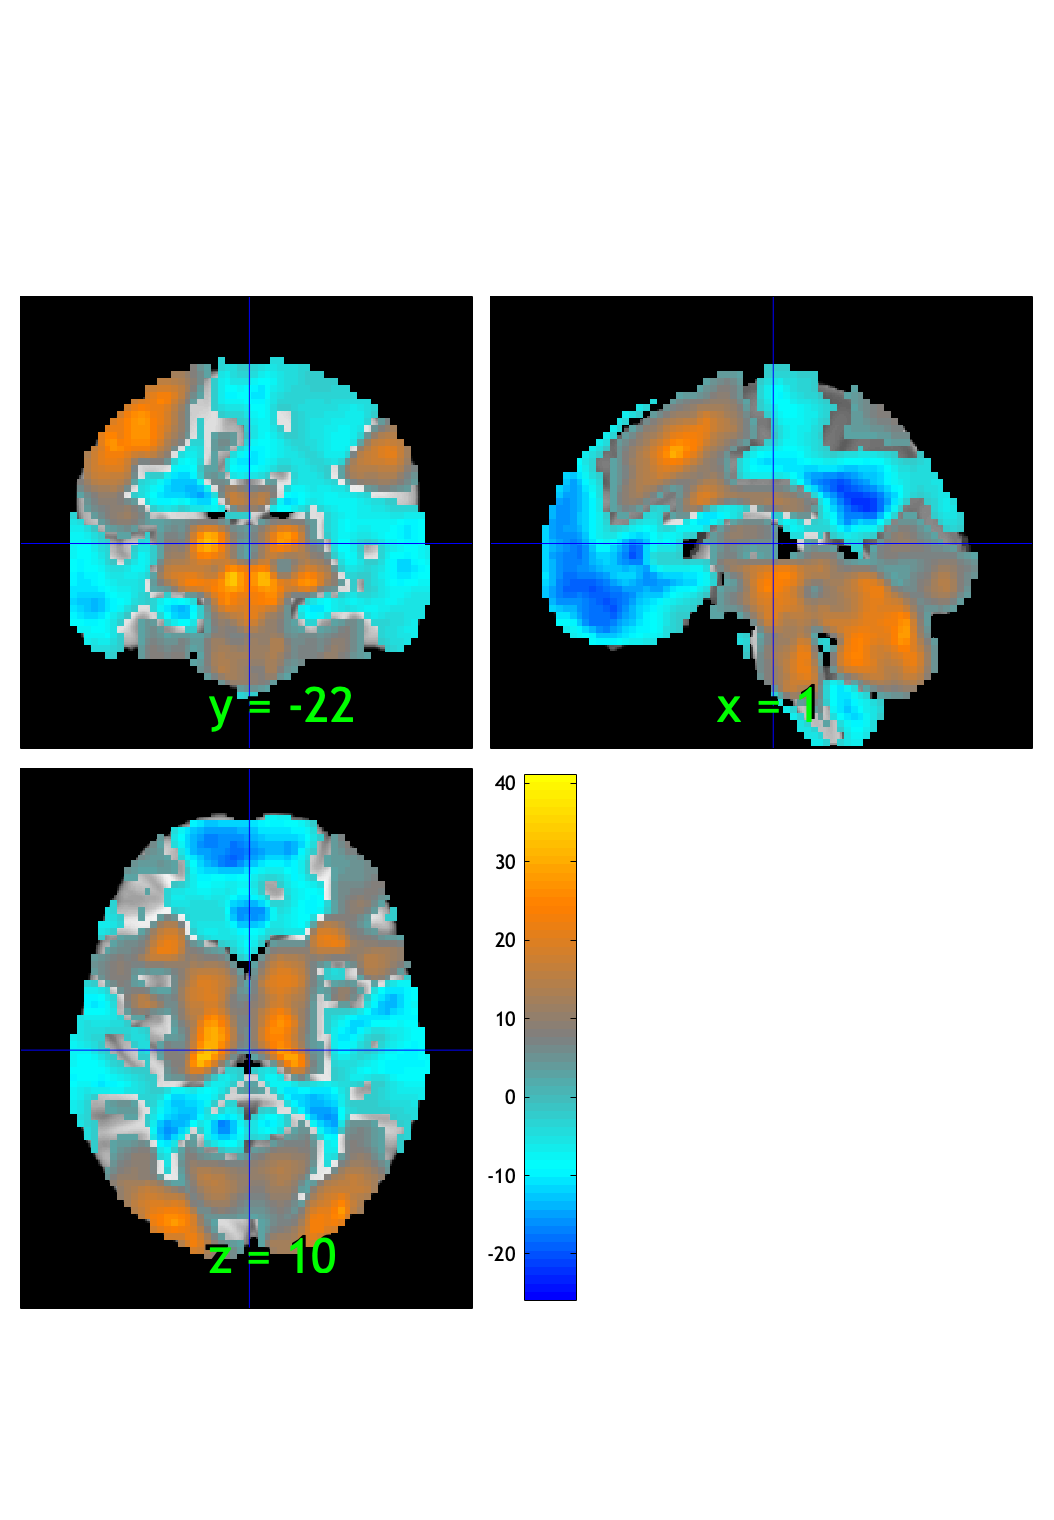

SPM12: spm_check_registration (v7759)              16:40:49 - 11/01/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


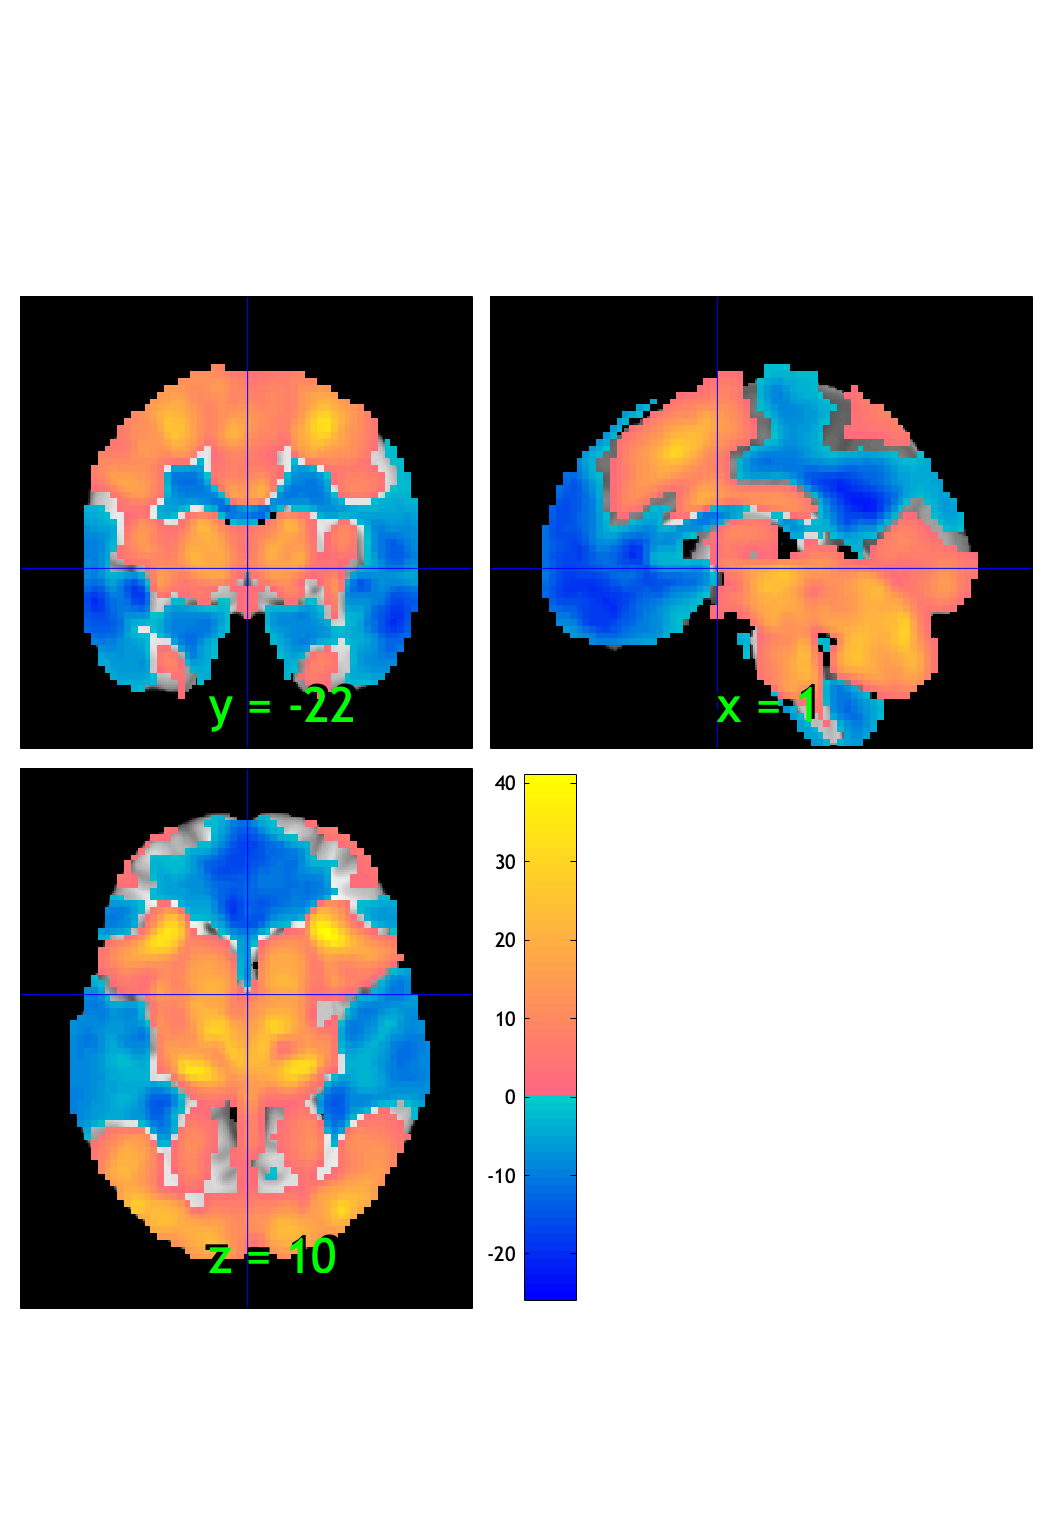

orthviews(fdr_t);

drawnow, snapnow;

create_figure('montage'); axis off;
montage(fdr_t);

Setting up fmridisplay objects


sagittal montage: 2185 voxels displayed, 83797 not displayed on these slices


sagittal montage: 2177 voxels displayed, 83805 not displayed on these slices


sagittal montage: 2152 voxels displayed, 83830 not displayed on these slices


axial montage: 16285 voxels displayed, 69697 not displayed on these slices


axial montage: 17537 voxels displayed, 68445 not displayed on these slices


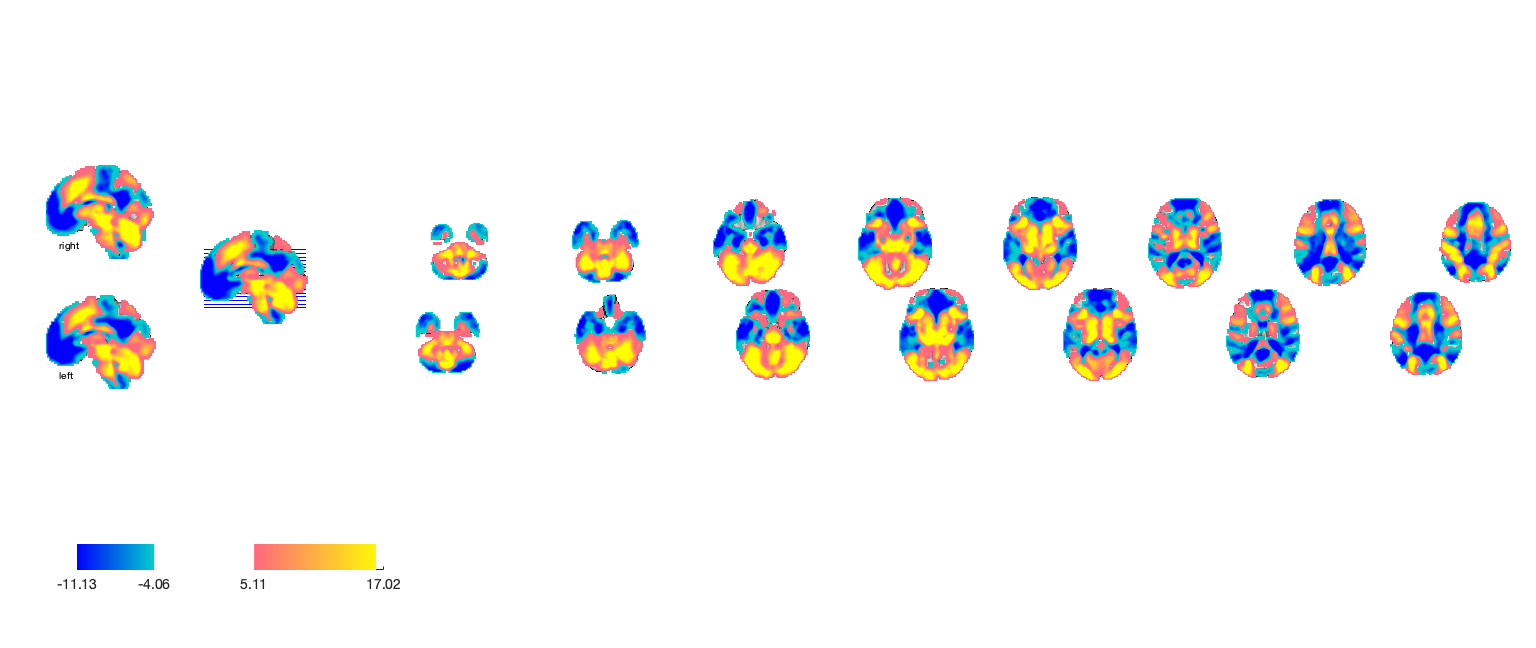

drawnow, snapnow;

#### Cognitive > PV :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low     words_low      testr_high      words_high   
    _________    ____________    __________    _______________

    -0.39138     {'trait'   }      0.4777      {'visual'     }
     -0.3555     {'personal'}     0.34246      {'object'     }
    -0.35308     {'person'  }     0.31678      {'letter'     }
    -0.34545     {'positive'}     0.31389      {'attention'  }
    -0.33942     {'rating'  }     0.30983      {'shape'      }
     -0.3378     {'negative'}     0.30774      {'objects'    }
    -0.33324     {'age'     }     0.30552      {'maintenance'}
    -0.31586     {'self'    }     0.29728      {'numbers'    }
    -0.30463     {'social'  }     0.28903      {'eye'        }
    -0.29928     {'affect'  }     0.28706      {'execution'  }



Cognitive > PV **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/CanlabCore/CanlabCore/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Can

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0569	-16.8686	0.0000	1.0000	
Cog Wholebrain	-0.0268	-10.5320	0.0000	1.0000	
Emo Wholebrain	0.0778	23.3377	0.0000	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.056911     0.0033655     -16.91    2.2204e-15     -1.717 
    {'Cog Wholebrain' }    -0.026768     0.0025403    -10.537    2.2204e-15    -1.0699 
    {'Emo Wholebrain' }      0.07778     0.0033205     23.424    2.2204e-15     2.3783 



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [9.0004 10.0004 11.0004]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 
Number of zero or NaN values within weight mask, by input image:
297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297 297


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}     -0.05441     0.0032393    -16.797    2.2204e-15     -1.7054
    {'Cog Wholebrain' }    -0.023613      0.002413    -9.7861    2.2204e-15    -0.99363
    {'Emo Wholebrain' }     0.073858     0.0032422      22.78    2.2204e-15       2.313



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {97×3 cell}
        text_han: {97×3 cell}
       point_han: {97×3 cell}
    star_handles: [12.0004 13.0004 14.0004]


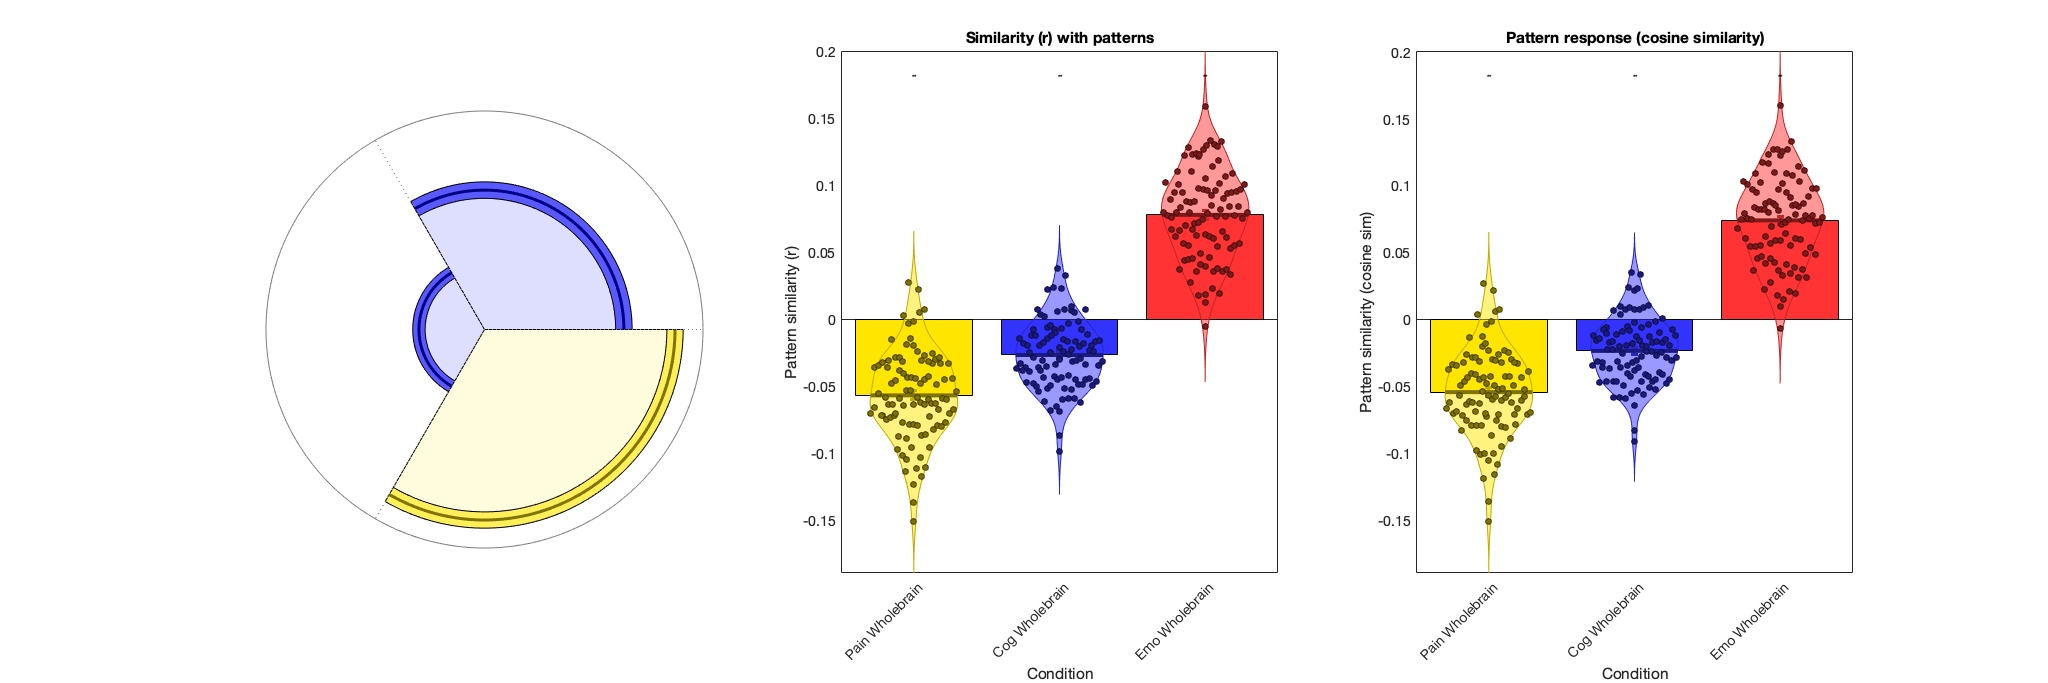

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;

% save html
pubdir = pwd;
pubfilename = 's03_PVC_stim_dummy_ROI.mlx';

p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
  'format', 'html', 'outputDir', pubdir, ...
  'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
htmlfile = publish(pubfilename, p);